# P4 Root Locus

clear; clc; close all;
addpath(genpath(fullfile(pwd, 'scripts')));

## Trim and reduced models

data = linearize_reduced_flight_dynamics_eul('CruiseSpeed', 70, 'DisplayReport', 'off');

trimSummary = table( ...
    data.trimPoint.inputs.front_collective_rpm, ...
    data.trimPoint.inputs.rear_collective_rpm, ...
    rad2deg(data.trimPoint.inputs.delta_e), ...
    rad2deg(data.trimPoint.eul(2)), ...
    norm(data.trimPoint.velocity), ...
    'VariableNames', {'front_collective_rpm','rear_collective_rpm','delta_e_deg','theta_deg','vinf_mps'})

trimSummary = 1×5 table
    front_collective_rpm    rear_collective_rpm    delta_e_deg    theta_deg    vinf_mps
    ____________________    ___________________    ___________    _________    ________

           1181.4                    0               -15.06        2.6325         70   


Longitudinal states: [u w q theta] Lateral states: [v p r phi]

Longitudinal controls: [prop.front prop.rear delta_e] Lateral controls: [delta_a delta_r`]`

A_long = data.long.A

A_long =    -0.0059    0.2022   -3.1209   -9.7996
   -0.2179   -1.3561   69.0594   -0.4506
    0.0105   -0.2184   -0.3174         0
         0         0    1.0000         0


B_long = data.long.B

B_long =     0.0006         0    0.6040
         0         0   -3.8494
   -0.0000         0   -2.9798
         0         0         0



A_lat = data.lat.A

A_lat =    -0.0851    3.0932  -69.6325    9.7996
   -0.0220   -2.5130    0.5334         0
    0.0272   -0.2516   -0.0844         0
         0    1.0000    0.0460         0


B_lat = data.lat.B

B_lat =          0   -3.8772
   25.3336   -0.7325
    1.0646    1.1396
         0         0


## Part A: pure dampers

Pure dampers use rate-over-control transfer functions.

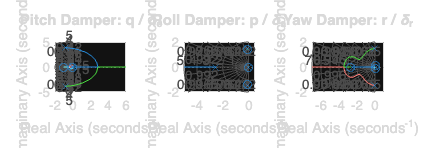

Gq = data.transfer.q_over_delta_e;
Gp = data.transfer.p_over_delta_a;
Gr = data.transfer.r_over_delta_r;

figure('Color', 'w', 'Position', [100 100 1200 420]);
tiledlayout(1,3);

nexttile;
rlocus(Gq);
grid on;
title('Pitch Damper: q / \delta_e');

nexttile;
rlocus(Gp);
grid on;
title('Roll Damper: p / \delta_a');

nexttile;
rlocus(Gr);
grid on;
title('Yaw Damper: r / \delta_r');



% sisotool(Gq)
% sisotool(Gp)
% Sisotool(Gr)

## Pick damper gains

Change these after looking at the root loci.

Kq_pick = 0.1;
Kp_roll_pick = 2;

A_long_q = data.long.A - data.long.B(:,3) * Kq_pick * [0 0 1 0];
A_lat_p = data.lat.A - data.lat.B(:,1) * Kp_roll_pick * [0 1 0 0];
disp(A_long_q)

   -0.0059    0.2022   -3.1813   -9.7996
   -0.2179   -1.3561   69.4444   -0.4506
    0.0105   -0.2184   -0.0194         0
         0         0    1.0000         0



disp(eig(A_lat_p))

 -53.1563 + 0.0000i
  -0.1005 + 1.4017i
  -0.1005 - 1.4017i
   0.0076 + 0.0000i



disp(eig(data.long.A))

  -0.8367 + 3.8535i
  -0.8367 - 3.8535i
  -0.0029 + 0.1975i
  -0.0029 - 0.1975i



disp(A_lat_p)

   -0.0851    3.0932  -69.6325    9.7996
   -0.0220  -53.1802    0.5334         0
    0.0272   -2.3809   -0.0844         0
         0    1.0000    0.0460         0



damperGainSummary = table(Kq_pick, Kp_roll_pick)

damperGainSummary = 1×2 table
    Kq_pick    Kp_roll_pick
    _______    ____________

      0.1           2      


## outer loops

Longitudinal option: airspeed-like u response to front collective 

Lateral option: bank angle response to aileron with roll damper locked in

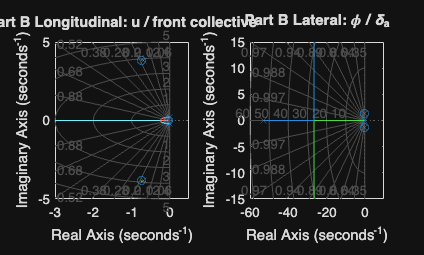

Gu = ss(A_long_q, data.long.B(:,1), [1 0 0 0], 0);
Gphi = ss(A_lat_p, data.lat.B(:,1), [0 0 0 1], 0);

figure();
tiledlayout(1,2);

nexttile;
rlocus(Gu);
grid on;
title('Part B Longitudinal: u / front collective');

nexttile;
rlocus(Gphi);
grid on;
title('Part B Lateral: \phi / \delta_a');


% sisotool(Gu)
% sisotool(Gphi)

## proportional longitudinal gain

Kv_pick = 50;

A_long_p = A_long_q - data.long.B(:,1) * Kv_pick * [1 0 0 0];
longPPoles = eig(A_long_p);

longPPoleTable = table(real(longPPoles), imag(longPPoles), ...
    'VariableNames', {'real_part','imag_part'})

longPPoleTable = 4×2 table
    real_part    imag_part
    _________    _________

     -0.68781      3.8419 
     -0.68781     -3.8419 
    -0.016826     0.20158 
    -0.016826    -0.20158 


## integral controller

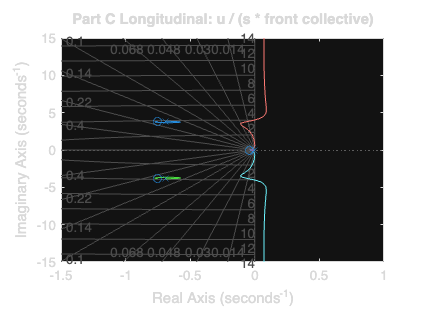

Gu_p = ss(A_long_p, data.long.B(:,1), [1 0 0 0], 0);
Gi = minreal(Gu_p / tf('s'));
sisotool(Gi)
figure('Color', 'w', 'Position', [100 100 560 420]);
rlocus(Gi);
grid on;
title('Part C Longitudinal: u / (s * front collective)');

## Pick one integral gain

Ki_pick = 30;  % could have more "stable" response with a gain of 20000 but it significantly reduced margins

A_long_pi = [A_long_p zeros(4,1); -[1 0 0 0] 0];
B_long_pi = [data.long.B(:,1); 0];
piPoles = eig(A_long_pi - B_long_pi * Ki_pick * [0 0 0 0 1]);

piPoleTable = table(real(piPoles), imag(piPoles), ...
    'VariableNames', {'real_part','imag_part'})

piPoleTable = 5×2 table
    real_part    imag_part
    _________    _________

     -0.68789      3.8419 
     -0.68789     -3.8419 
    -0.029457     0.15767 
    -0.029457    -0.15767 
      0.02541           0 


## Final chosen gains

gainSummary = table(Kq_pick, Kp_roll_pick, Kv_pick, Ki_pick)

gainSummary = 1×4 table
    Kq_pick    Kp_roll_pick    Kv_pick    Ki_pick
    _______    ____________    _______    _______

      0.1           2            50         30   
